# ECE203 PreLab 04:  Beat Frequencies

Barry Van Veen (June 15, 2018), Adapted to Live Script by Eduardo R Arvelo (Jan 2021) 

## Set up workspace

close all
clear

t = 0:.0001:2; %time samples
length(t)

ans = 20001

## Case 1:

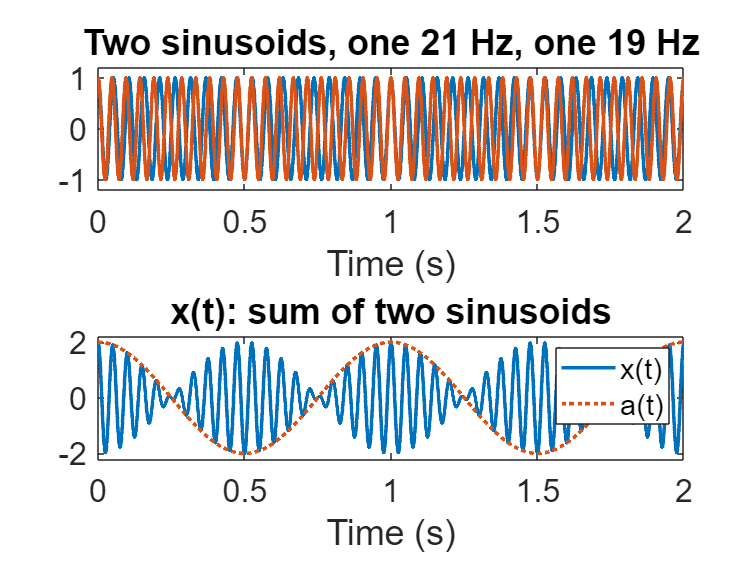

f1 = 19;  % Sinusoid 1 frequency
f2 = 21;  % Sinusoid 2 frequency

s1 = cos(2*pi*f1*t);
s2 = cos(2*pi*f2*t);

sum = s1+s2;

a = 2*cos(pi*(f2-f1)*t);  % corresponding AM message

subplot(211)
plot(t,s1,t,s2,'linewidth',2)
ylim([-1.2,1.2])
xlabel('Time (s)')
title(['Two sinusoids, one ', num2str(f2), ' Hz, one ',  num2str(f1), ' Hz'])
set(gca,'FontSize',18)

subplot(212)
plot(t,sum,t,a,':','linewidth',2)
legend('x(t)','a(t)')
title('x(t): sum of two sinusoids')
ylim([-2.2,2.2])
xlabel('Time (s)')
set(gca,'FontSize',18)

## Dependence of interpretation on length of time window 

## Case 2: Part 1 

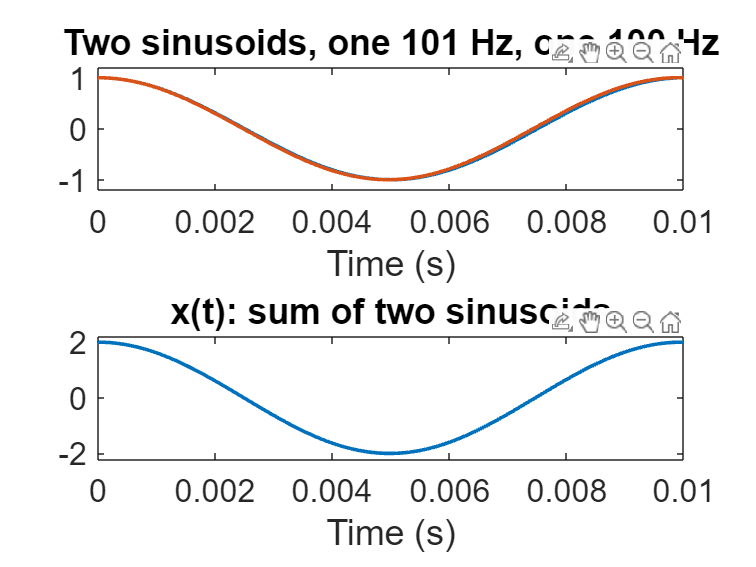

t = 0:.0001:1;  % dense sampling in time
f1 = 100;
f2 = 101;

s1 = cos(2*pi*f1*t);
s2 = cos(2*pi*f2*t);

sum = s1+s2;

window = [0,0.01]; % plot sum from first entry to second entry of window

subplot(211)
plot(t,s1,t,s2,'linewidth',2)
xlim(window)  % limits plot to times set in window
ylim([-1.2,1.2])
xlabel('Time (s)')
title(['Two sinusoids, one ', num2str(f2), ' Hz, one ',  num2str(f1), ' Hz'])
set(gca,'FontSize',18)

subplot(212)
plot(t,sum,'linewidth',2)
title('x(t): sum of two sinusoids')
xlim(window)  % limits plot to times set in window
ylim([-2.2,2.2])
xlabel('Time (s)')
set(gca,'FontSize',18)

## Case 2: Part 2

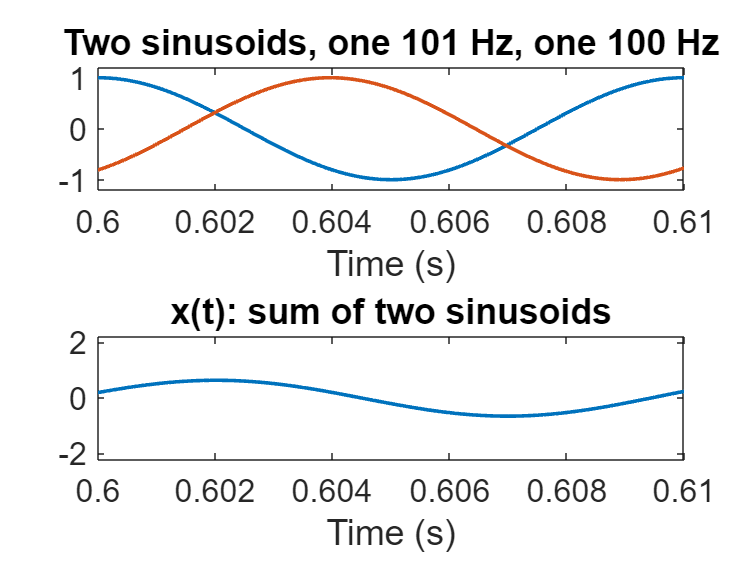


window = [0.6,0.61]; % plot sum from first entry to second entry of window

subplot(211)
plot(t,s1,t,s2,'linewidth',2)
xlim(window)  % limits plot to times set in window
ylim([-1.2,1.2])
xlabel('Time (s)')
title(['Two sinusoids, one ', num2str(f2), ' Hz, one ',  num2str(f1), ' Hz'])
set(gca,'FontSize',18)

subplot(212)
plot(t,sum,'linewidth',2)
title('x(t): sum of two sinusoids')
xlim(window)  % limits plot to times set in window
ylim([-2.2,2.2])
xlabel('Time (s)')
set(gca,'FontSize',18)

## Case 2: Part 3

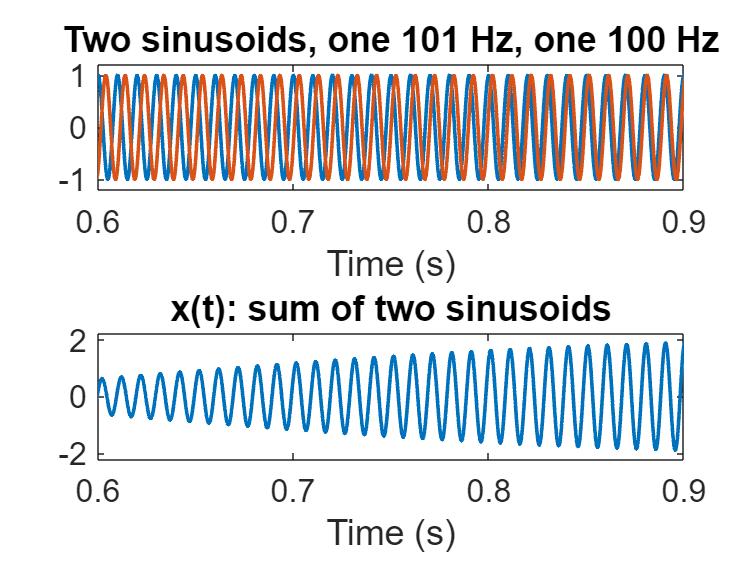


window = [0.6,0.9]; % plot sum from first entry to second entry of window

subplot(211)
plot(t,s1,t,s2,'linewidth',2)
xlim(window)  % limits plot to times set in window
ylim([-1.2,1.2])
xlabel('Time (s)')
title(['Two sinusoids, one ', num2str(f2), ' Hz, one ',  num2str(f1), ' Hz'])
set(gca,'FontSize',18)

subplot(212)
plot(t,sum,'linewidth',2)
title('x(t): sum of two sinusoids')
xlim(window)  % limits plot to times set in window
ylim([-2.2,2.2])
xlabel('Time (s)')
set(gca,'FontSize',18)